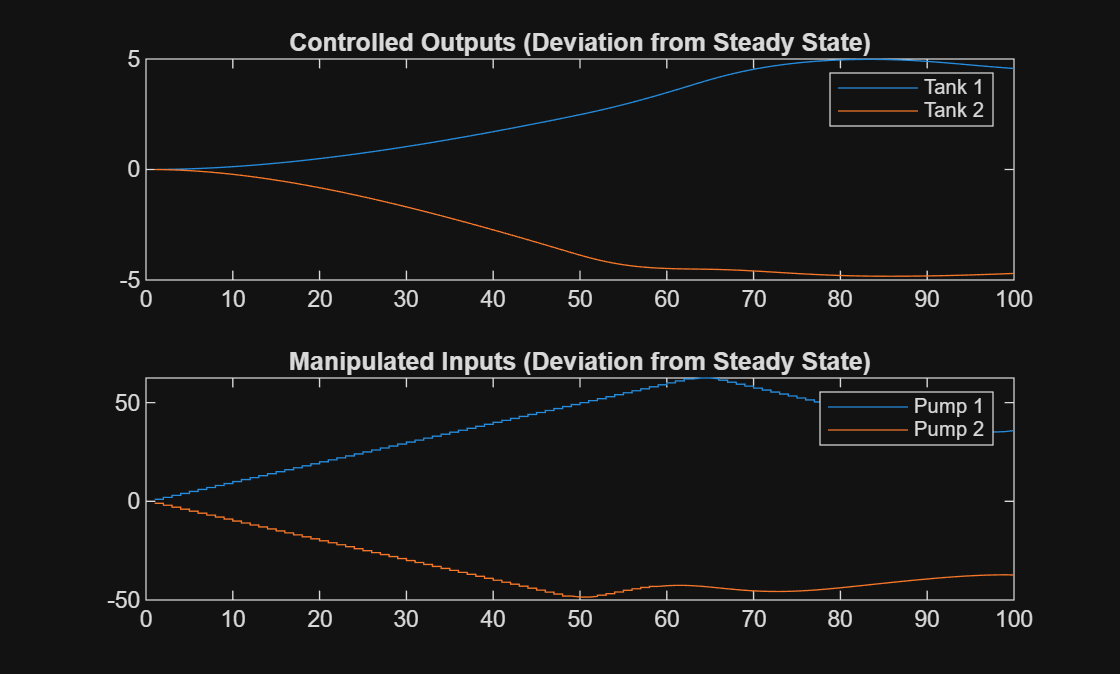

clearvars; clc; close all;

% Load discrete state-space model from Problem 4
load('sysd_stochastic.mat', 'Ad_stochastic', 'Bd_stochastic', 'Cd_stochastic');

Ad = Ad_stochastic;
Bd = Bd_stochastic;
Cd = Cd_stochastic;

Cz = Cd(1:2, :);
nx = size(Ad, 1); nu = size(Bd, 2); nz = size(Cz, 1);
Gd = zeros(nx, 2); nw = 2; % No unmeasured disturbances modeled yet

% 2. Controller Design Parameters
N = 4; % Extended horizon for better stability
Wz  = diag([10, 10]); 
Wu  = diag([0.1, 0.1]); 
Wdu = diag([1, 1]);    

umin  = -100*ones(nu, 1);
umax  =  100*ones(nu, 1);
dumin = -1*ones(nu, 1);
dumax =  1*ones(nu, 1);

mpc = mpc_design(Ad, Bd, Gd, Cz, N, Wz, Wu, Wdu, umin, umax, dumin, dumax);

% 4. Simulation Setup
Nsim = 100;
x_sim = zeros(nx, Nsim+1);
u_sim = zeros(nu, Nsim);
y_sim = zeros(nz, Nsim);

% Initial conditions (Deviation variables)

x_sim(:, 1) = zeros(nx, 1); 
u_prev = zeros(nu, 1);
w_k = zeros(nw, 1);
U_bar = zeros(N * nu, 1); 
R_k = repmat([5; -5], N, 1);% Step targets: Tank 1 (+5), Tank 2 (-5)
xinit  = zeros(N * nu, 1); 

% 5. Closed-Loop Simulation
for k = 1:Nsim
    % Compute control action
    [uk, Uk, Zk, info] = mpc_compute(mpc, x_sim(:, k), w_k, u_prev, R_k, U_bar, xinit);

    % Store and apply control action
    u_sim(:, k) = uk;
    u_prev = uk;

    % Plant evolution (using linear model for testing)
    x_sim(:, k+1) = Ad * x_sim(:, k) + Bd * uk;
    y_sim(:, k) = Cz * x_sim(:, k);
end

% Plotting results
figure;
subplot(2,1,1);
plot(1:Nsim, y_sim(1,:), 1:Nsim, y_sim(2,:));
title('Controlled Outputs (Deviation from Steady State)'); legend('Tank 1', 'Tank 2');
subplot(2,1,2);
stairs(1:Nsim, u_sim(1,:)); hold on; stairs(1:Nsim, u_sim(2,:));
title('Manipulated Inputs (Deviation from Steady State)'); legend('Pump 1', 'Pump 2');